# Signal Processing I

**Author: Chul Min Yeum**

**Email: cmyeum@uwaterloo.ca**

Last updated: 2019-12-25

### Perioidc Signals 

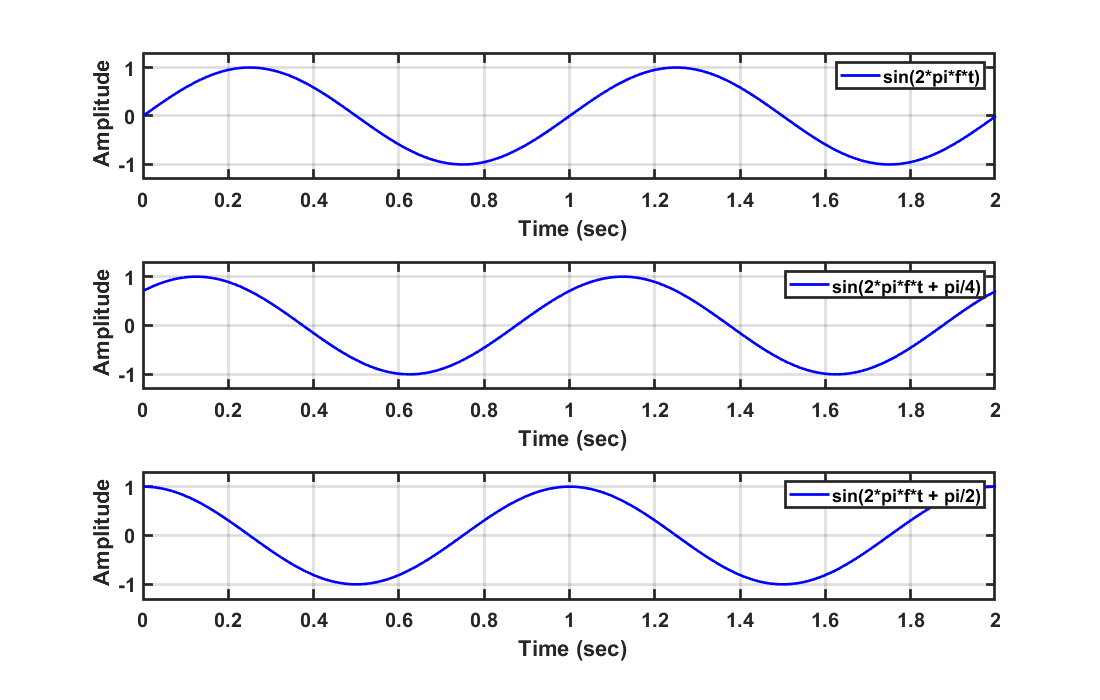

syms t   

f = 1;
y1 = sin(2*pi*f*t);
y2 = sin(2*pi*f*t + pi/4);
y3 = sin(2*pi*f*t + pi/2);

% the signal is assumed to be analog (very high sampling rate). 
ncyle = 2;
fs = 1000; % # of samples per a second
ta = 0:1/fs:ncyle;
y1 = subs(y1, t, ta);
y2 = subs(y2, t, ta);
y3 = subs(y3, t, ta);


% plot the signals
fig1 = figure(1);
set(fig1,'Position', [100 100 1100 700]);

subplot(311); plot(ta,y1,'-b', 'linewidth', 2);hold on;
legend('sin(2*pi*f*t)'); axis tight;grid on;
ylabel('\bf Amplitude'); ylim([-1.3 1.3]);
xlabel('\bf Time (sec)');
set(gca,'fontsize',15,'linewidth',2,'fontweight','bold');

subplot(312); plot(ta,y2,'-b', 'linewidth', 2);hold on;
legend('sin(2*pi*f*t + pi/4)'); axis tight;grid on;
ylabel('\bf Amplitude'); ylim([-1.3 1.3]);
xlabel('\bf Time (sec)');
set(gca,'fontsize',15,'linewidth',2,'fontweight','bold');

subplot(313); plot(ta,y3,'-b', 'linewidth', 2);hold on;
legend('sin(2*pi*f*t + pi/2)'); axis tight;grid on;
ylabel('\bf Amplitude'); ylim([-1.3 1.3]);
xlabel('\bf Time (sec)');
set(gca,'fontsize',15,'linewidth',2,'fontweight','bold');

### Square Wave (General form)

clear; clc ; close all;

% this signal is assumed to be analog. 
ncyle = 3;
Fsa = 1000; % # of samples per a second (assumed to be infinite)
Tp = 2;
t = -ncyle*Tp:1/Fsa:ncyle*Tp;
x = @(t) square(t*(2*pi)/Tp); % original signal


$$x\left(t\right)=\frac{a_0 }{2}+\sum_{n=0}^{\infty } a_n \mathrm{cos}\left(\frac{2\pi \mathrm{nt}}{T_p }\right)+b_n \mathrm{sin}\left(\frac{2\pi \mathrm{nt}}{T_p }\right)$$


a0 = 1/Tp*integral(x, -Tp/2, Tp/2);

nCoeff = 5;
a = zeros(nCoeff,1);
b = zeros(nCoeff,1);
for ii=1:nCoeff
    fun_a = @(t) x(t).*cos(2*pi*ii*t/Tp);
    a(ii) = integral(fun_a, -Tp/2, Tp/2);
    
    fun_b = @(t) x(t).*sin(2*pi*ii*t/Tp);
    b(ii) = integral(fun_b, -Tp/2, Tp/2);
end

% numerical integration
sig_y_numeric = zeros(nCoeff, numel(t));
sig_y_analytic = zeros(nCoeff, numel(t));
for ii=1:nCoeff
    if ii==1
        sig_y_numeric(ii,:) = ...
            a0/2 + a(ii)*cos(2*pi*ii*t/Tp) + b(ii)*sin(2*pi*ii*t/Tp);
    else
        sig_y_numeric(ii,:) = ...
            sig_y_numeric(ii-1,:) + a(ii)*cos(2*pi*ii*t/Tp) + b(ii)*sin(2*pi*ii*t/Tp);
    end
end

% analytic integration
for ii=1:nCoeff
    sig_y_analytic(ii,:) = x_analytic(t, Tp, ii);
end


$$x\left(t\right)=\sum_{n=0}^{\infty } \frac{2}{n\pi }\left(1-\mathrm{cosn}\pi \right)\sin \left(\frac{2\pi \textrm{nt}}{T_p }\right)$$


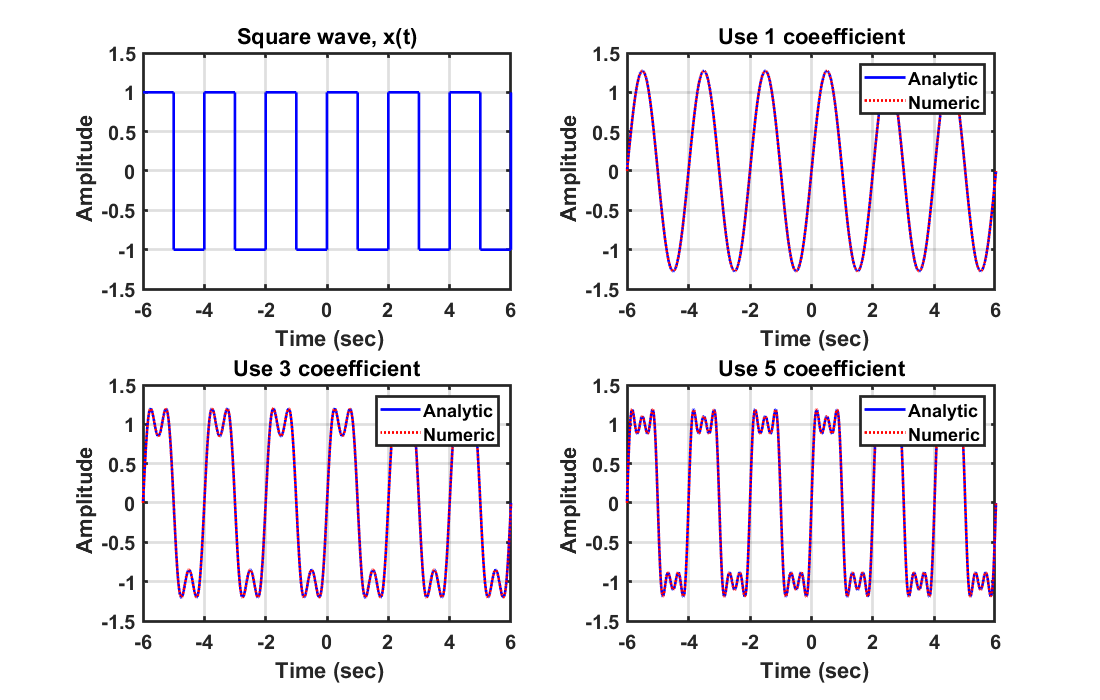

% plot the signals
fig1 = figure(1);
set(fig1,'Position', [100 100 1100 700]);

subplot(221); plot(t,x(t),'-b', 'linewidth', 2);
axis tight;grid on;
title('Square wave, x(t)')
ylabel('\bf Amplitude'); ylim([-1.5 1.5]);
xlabel('\bf Time (sec)');
set(gca,'fontsize',15,'linewidth',2,'fontweight','bold');

subplot(222); plot(t,sig_y_numeric(1,:),'-b', 'linewidth', 2); hold on;
plot(t,sig_y_analytic(1,:),':r', 'linewidth', 2);
axis tight;grid on; hold off;
title('Use 1 coeefficient')
ylabel('\bf Amplitude'); ylim([-1.5 1.5]);
xlabel('\bf Time (sec)');
legend('Analytic', 'Numeric');
set(gca,'fontsize',15,'linewidth',2,'fontweight','bold');

subplot(223); plot(t,sig_y_numeric(3,:),'-b', 'linewidth', 2); hold on;
plot(t,sig_y_analytic(3,:),':r', 'linewidth', 2);
axis tight;grid on; hold off;
title('Use 3 coeefficient')
ylabel('\bf Amplitude'); ylim([-1.5 1.5]);
xlabel('\bf Time (sec)');
legend('Analytic', 'Numeric');
set(gca,'fontsize',15,'linewidth',2,'fontweight','bold');

subplot(224); plot(t,sig_y_numeric(nCoeff,:),'-b', 'linewidth', 2); hold on;
plot(t,sig_y_analytic(nCoeff,:),':r', 'linewidth', 2);
axis tight;grid on; hold off;
title('Use 5 coeefficient')
ylabel('\bf Amplitude'); ylim([-1.5 1.5]);
xlabel('\bf Time (sec)');
legend('Analytic', 'Numeric');
set(gca,'fontsize',15,'linewidth',2,'fontweight','bold');

### Square Wave (Complex Form)

clear; clc ; close all;

% this signal is assumed to be analog. 
ncyle = 3;
Fsa = 1000; % # of samples per a second (assumed to be infinite)
Tp = 2;
t = -ncyle*Tp:1/Fsa:ncyle*Tp;
x = @(t) square(t*(2*pi)/Tp); % original signal

% general form
a0 = integral(x, -Tp/2, Tp/2);
nCoeff = 5;
a = zeros(nCoeff,1);
b = zeros(nCoeff,1);
sig_y_general = zeros(nCoeff, numel(t));
for ii=1:nCoeff
    fun_a = @(t) x(t).*cos(2*pi*ii*t/Tp);
    a(ii) = integral(fun_a, -Tp/2, Tp/2);
    
    fun_b = @(t) x(t).*sin(2*pi*ii*t/Tp);
    b(ii) = integral(fun_b, -Tp/2, Tp/2);
    
    if ii==1
        sig_y_general(ii,:) = a0 + a(ii)*cos(2*pi*ii*t/Tp) + b(ii)*sin(2*pi*ii*t/Tp);
    else
        sig_y_general(ii,:) = sig_y_general(ii-1,:) + a(ii)*cos(2*pi*ii*t/Tp) + b(ii)*sin(2*pi*ii*t/Tp);
    end
end


$$x\left(t\right)=\sum_{n=-\infty }^{\infty } c_n e^{\mathrm{i2}\pi \mathrm{nt}/T_p }$$


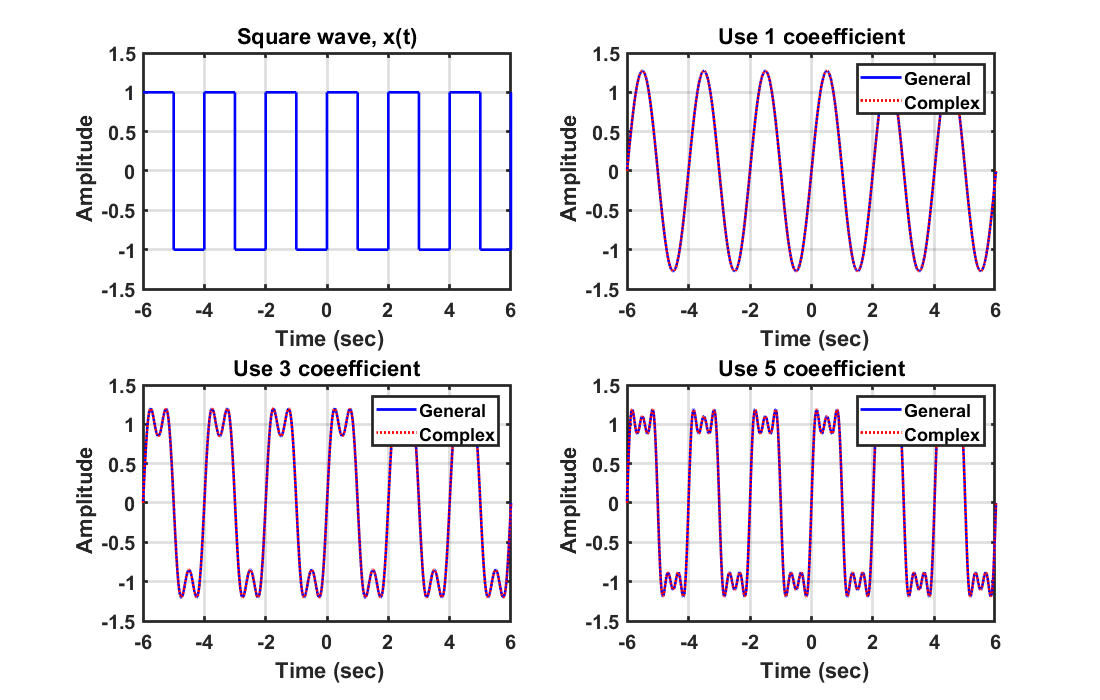

% complex form
sig_y_complex_all = zeros(2*nCoeff+1, numel(t));
count = 1;
for ii=-nCoeff:nCoeff
    fun = @(t) x(t).*exp(-sqrt(-1)*2*pi*ii*t/Tp);
    sig_y_complex_all(count,:) = 1/Tp* integral(fun, 0, Tp)*exp(sqrt(-1)*2*pi*ii*t/Tp);
    count = count + 1;
end

sig_y_complex = zeros(nCoeff, numel(t));
for ii=1:nCoeff
    rowId = (nCoeff-ii+1):(nCoeff+ii+1);
    sig_y_complex(ii,:) = sum(sig_y_complex_all(rowId,:));
end

fig1 = figure(1);
set(fig1,'Position', [100 100 1100 700]);

subplot(221); plot(t,x(t),'-b', 'linewidth', 2);
axis tight;grid on;
title('Square wave, x(t)')
ylabel('\bf Amplitude'); ylim([-1.5 1.5]);
xlabel('\bf Time (sec)');
set(gca,'fontsize',15,'linewidth',2,'fontweight','bold');

subplot(222); plot(t,sig_y_general(1,:),'-b', 'linewidth', 2); hold on;
plot(t,real(sig_y_complex(1,:)),':r', 'linewidth', 2);
axis tight;grid on; hold off;
title('Use 1 coeefficient')
ylabel('\bf Amplitude'); ylim([-1.5 1.5]);
xlabel('\bf Time (sec)');
legend('General', 'Complex');
set(gca,'fontsize',15,'linewidth',2,'fontweight','bold');

subplot(223); plot(t,sig_y_general(3,:),'-b', 'linewidth', 2); hold on;
plot(t,real(sig_y_complex(3,:)),':r', 'linewidth', 2);
axis tight;grid on; hold off;
title('Use 3 coeefficient')
ylabel('\bf Amplitude'); ylim([-1.5 1.5]);
xlabel('\bf Time (sec)');
legend('General', 'Complex');
set(gca,'fontsize',15,'linewidth',2,'fontweight','bold');

subplot(224); plot(t,sig_y_general(nCoeff,:),'-b', 'linewidth', 2); hold on;
plot(t,real(sig_y_complex(nCoeff,:)),':r', 'linewidth', 2);
axis tight;grid on; hold off;
title('Use 5 coeefficient')
ylabel('\bf Amplitude'); ylim([-1.5 1.5]);
xlabel('\bf Time (sec)');
legend('General', 'Complex');
set(gca,'fontsize',15,'linewidth',2,'fontweight','bold');

function x = x_analytic (t, Tp, n)
% square wave
x = zeros(1, numel(t));
for ii=1:n
    x = x + 2/(ii*pi)*(1-cos(ii*pi))*sin(2*pi*ii*t/Tp);
end
end